## Parcial Mvalenciao

### Punto 1

%arx 221
clf
Datos = [-1 0 0;
         0 1 0.0003;
         1 1 3.5056;
         2 1 2.8088;
         3 1 2.8067;
         4 1 2.7879;
         5 1 2.7883;
         6 1 2.7888;
         7 1 2.7939];
[phi, Y, param, cova] = OLS(Datos, 2, 2, 1);
%Notar que phi no esta bien definida, por lo que phi'*phi no tiene inversa 
phi, inv(phi'*phi)

phi =    -0.0003         0    1.0000         0
   -3.5056   -0.0003    1.0000    1.0000
   -2.8088   -3.5056    1.0000    1.0000
   -2.8067   -2.8088    1.0000    1.0000
   -2.7879   -2.8067    1.0000    1.0000
   -2.7883   -2.7879    1.0000    1.0000
   -2.7888   -2.7883    1.0000    1.0000


ans =    37.3449    8.4941    0.0112  129.6319
    8.4941    2.0636    0.0025   29.8071
    0.0112    0.0025    1.0000   -0.9611
  129.6319   29.8071   -0.9611  451.9359


G = tf(param(3:end)',[1 param(1:2)'],'ts',1)

G =
 
      3.506 z - 1.075
  -----------------------
  z^2 - 0.108 z - 0.02077
 
Sample time: 1 seconds
Discrete-time transfer function.



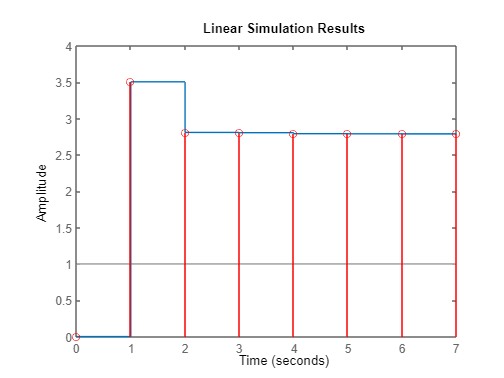

lsim(G,ones(8,1),linspace(0,7,8))
hold on
stem(Datos(2:end,1),Datos(2:end,3),"Color",'r')

sqrt(diag(cova)) %Desviacio estandar de los parametros

ans =     0.0186
    0.0044
    0.0030
    0.0648


data = iddata(Y,phi(:,end),1);
orden_excit = pexcit(data)%orden de excitacion del modelo

orden_excit = 2

### Punto 2

clear all, clf, clc
A = [-1/20 1/20
    1/20 -1/10];
B = [0.001
    0];
C = [0 1]; % Variable a usar para corrección
D = 0;
Ts = 0.1;
sys = ss(A,[B B],C,D,Ts,'InputName',{'u' 'w'},'OutputName','y');
Q = 0.01;
R = 0.05^2;
[kalmf,L,~,Mx,Z] = kalman(sys,Q,R);
kalmf = kalmf(1,:);

ans = 1

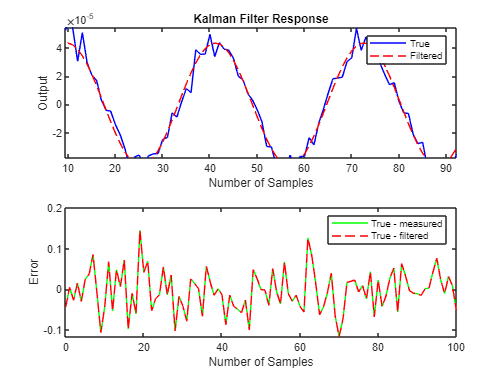

sys.InputName = {'u','w'};
sys.OutputName = {'yt'};
vIn = sumblk('y=yt+v');
kalmf.InputName = {'u','y'};
kalmf.OutputName = 'ye';
SimModel = connect(sys,vIn,kalmf,{'u','w','v'},{'yt','ye'});
t = (0:100)';
u = sin(t/5);
rng('default');
w = sqrt(Q)*randn(length(t),1);
v = sqrt(R)*randn(length(t),1);
out = lsim(SimModel,[u,w,v]);
yt = out(:,1); % respuesta real
ye = out(:,2); % respuesta filtrada
y = yt + v; % respuesta medida
clf
subplot(211), plot(t,yt,'b',t,ye,'r--'),
xlabel('Number of Samples'), ylabel('Output')
title('Kalman Filter Response')
legend('True','Filtered')
subplot(212), plot(t,y-yt,'g',t,y-ye,'r--'),
xlabel('Number of Samples'), ylabel('Error')
legend('True - measured','True - filtered')

## Parcial Asepulvede

### Punto 2

clear all, clf, clc
syms x1 x2 u
a = 0.01; b = 0.02; %Constantes definidas por el usuario

ode1 = -x1 +a*x2*(1+x1);
ode2 = -b*x1*(1+x1)+u;
y = x1;

odes = [ode1; ode2]; vars = [x1, x2];

[A, B, C, D] = linealizacion(odes,y,vars,u)

$$A = \left(\begin{array}{cc} 0.0100\,x_{2}-1 & 0.0100\,x_{1}+0.0100\\ -0.0400\,x_{1}-0.0200 & 0 \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

$$C = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

D = 0

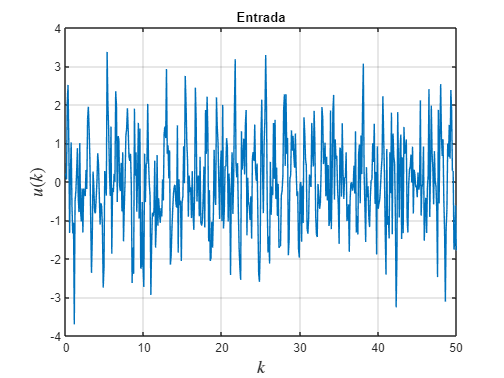

Ts = 0.1; % tiempo de muestreo T.
tiempo = 0:Ts:50; % periodo de tiempo a usar.
u = sin(5*tiempo) + randn(1,length(tiempo)); %ones(1, length(tiempo));

plot(tiempo, u)
title('Entrada');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$u(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
grid on

% Condiciones iniciales dados por el usuario:
M = 0.001*eye(2); R=100; P0 = M; x0 = [1 1]'; Ts = 0.1;
%odes = matlabFunction(odes);
%Obtenemos los valores de y reales en cada tiempo t
[t, x] = ode45(@(t,x) ode(t, x, u, tiempo, odes), tiempo, x0); 
y = x(:,1);

V = 0.1*randn(length(y),2);
y1 = y + V;
[P_trace, K_norm, x_est] = KalmanExtended(A,C,odes,t,x,u,y1,x0,M,R,P0,Ts,V);

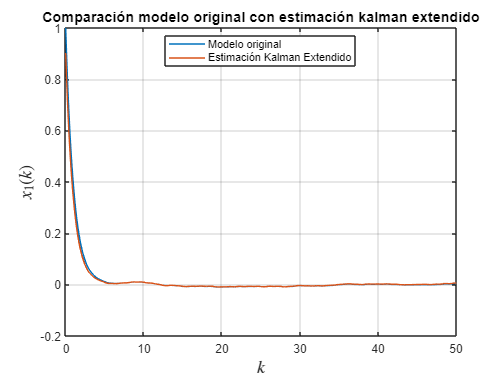

clf
plot(t, x(:,1), t, x_est(:,1))
legend({'Modelo original', 'Estimación Kalman Extendido'}, 'Location', 'best');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x_{1}(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Comparación modelo original con estimación kalman extendido', 'FontSize', 12);
grid on

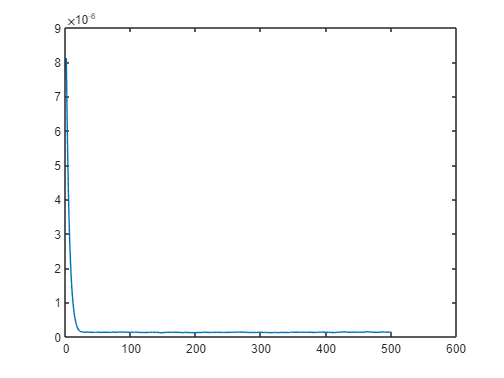

clf
plot(K_norm) 

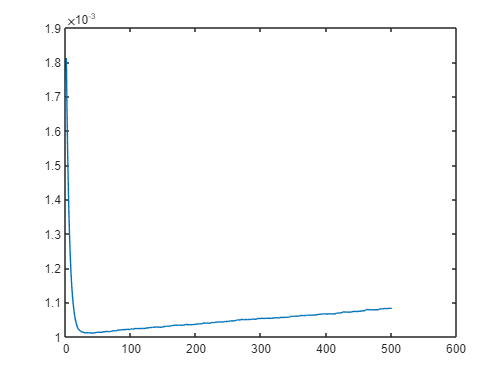

plot(P_trace)

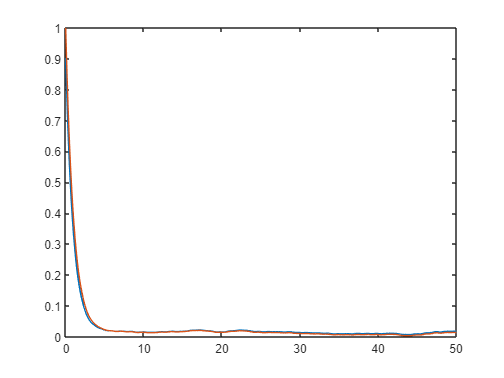

clf
plot(t,x_est(:,1))
hold on
plot(t,y)